# Ex09. Introduction to Signals and systems

### s1320112/ Motohisa YAMANO

## 1. Plot FIR Filter Signals

This assignment involves generating six figures for an FIR filter using MATLAB functions such as meshgrid, plot3, stem, meshc, roots, zplane, and phase. For the numerical computations, the constant a is set to 0.5, with z defined as ω. The resulting waveforms are organized into a 3 * 2 subplot grid to facilitate comparative analysis.

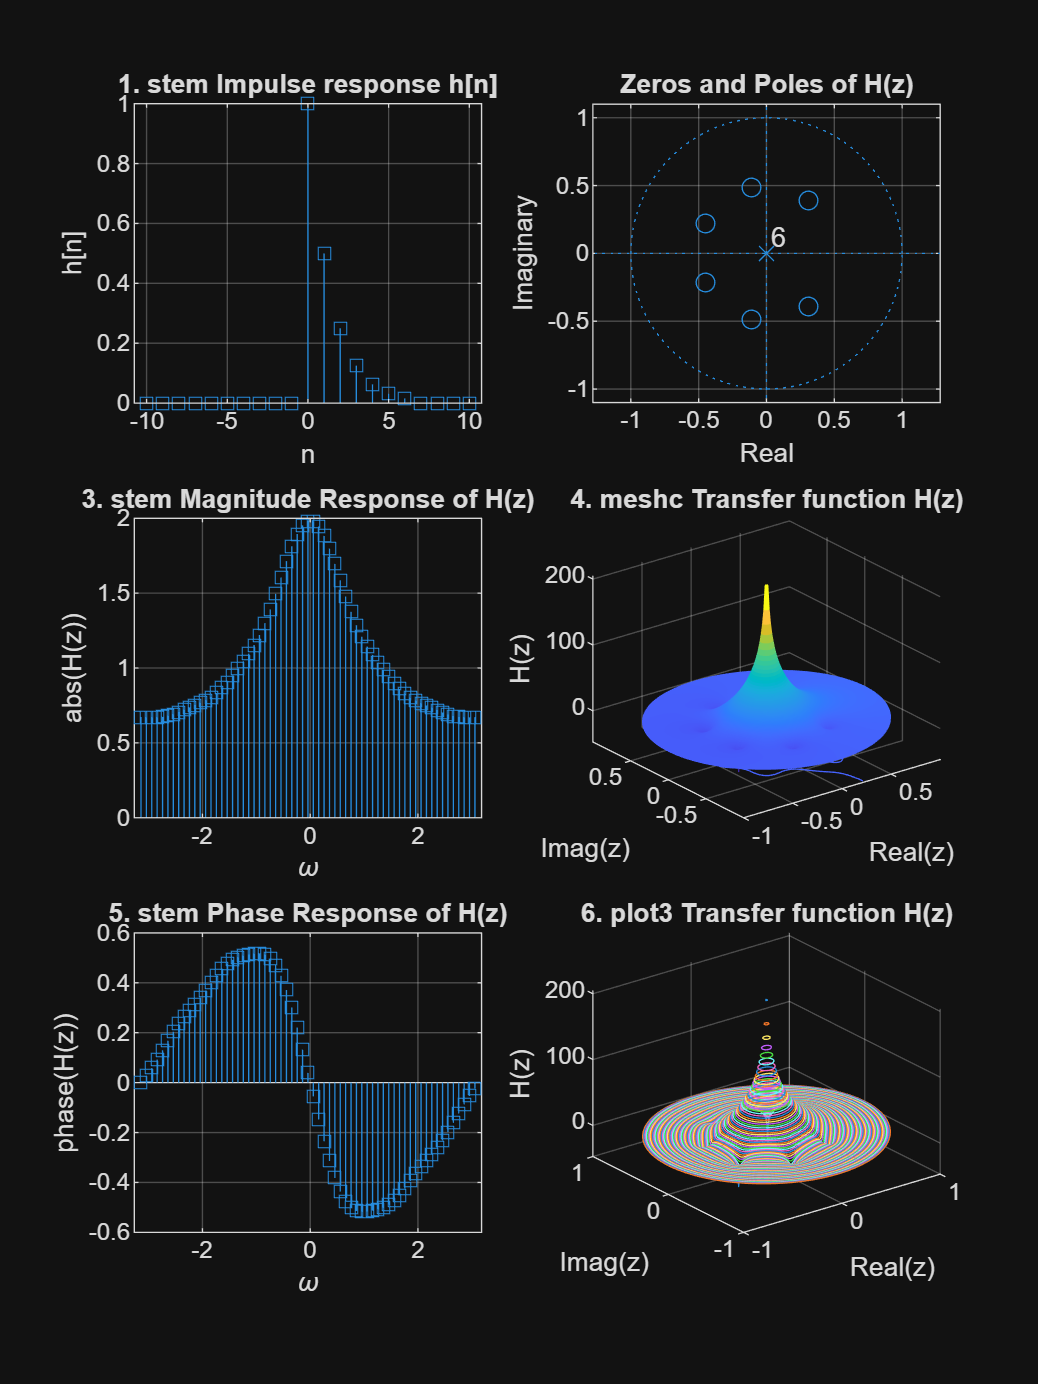

a = 0.5;
r = 0:0.01:1;
omega = -pi:0.01:pi;
[R, OMEG] = meshgrid(r, omega);
Z = R .* exp(1j * OMEG);
n = -10:1:10;

h = @(n) a.^n .* ((n >= 0) - (n >= 7));
H = @(z) ((1 - a.^7 .* z.^(-7)) ./ (1 - a .* z.^(-1)));

figure('Position', [100, 100, 600, 800]);

subplot(3, 2, 1);
p1 = stem(n, h(n), 's-');
title('1. stem Impulse response h[n]');
xlabel('n');
ylabel('h[n]');
grid on;

subplot(3, 2, 2);
b = a.^(0:6);
p2 = zplane(b, 1);
title('Zeros and Poles of H(z)');
xlabel('Real');
ylabel('Imaginary');
grid on;

subplot(3, 2, 4);
p4 = meshc(real(Z), imag(Z), 20 * log10(abs(H(Z))));
title('4. meshc Transfer function H(z)');
xlabel('Real(z)');
ylabel('Imag(z)');
zlabel('H(z)');
grid on;

subplot(3, 2, 6);
p6 = plot3(real(Z), imag(Z), 20 * log10(abs(H(Z))));
title('6. plot3 Transfer function H(z)');
xlabel('Real(z)');
ylabel('Imag(z)');
zlabel('H(z)');
grid on;


subplot(3, 2, 3);
r = 1;
omega = -pi:0.1:pi;
[R, OMEG] = meshgrid(r, omega);
Z = r .* exp(1j * OMEG);
p3 = stem(OMEG, abs(H(Z)), 's-');
title('3. stem Magnitude Response of H(z)');
xlabel('\omega');
ylabel('abs(H(z))');
grid on;

subplot(3, 2, 5);
p5 = stem(OMEG, phase(H(Z)), 's-');
title('5. stem Phase Response of H(z)');
xlabel('\omega');
ylabel('phase(H(z))');
grid on;

## 2. Math Problem

Below is the snapshot of my answer in fill-blank math problem.